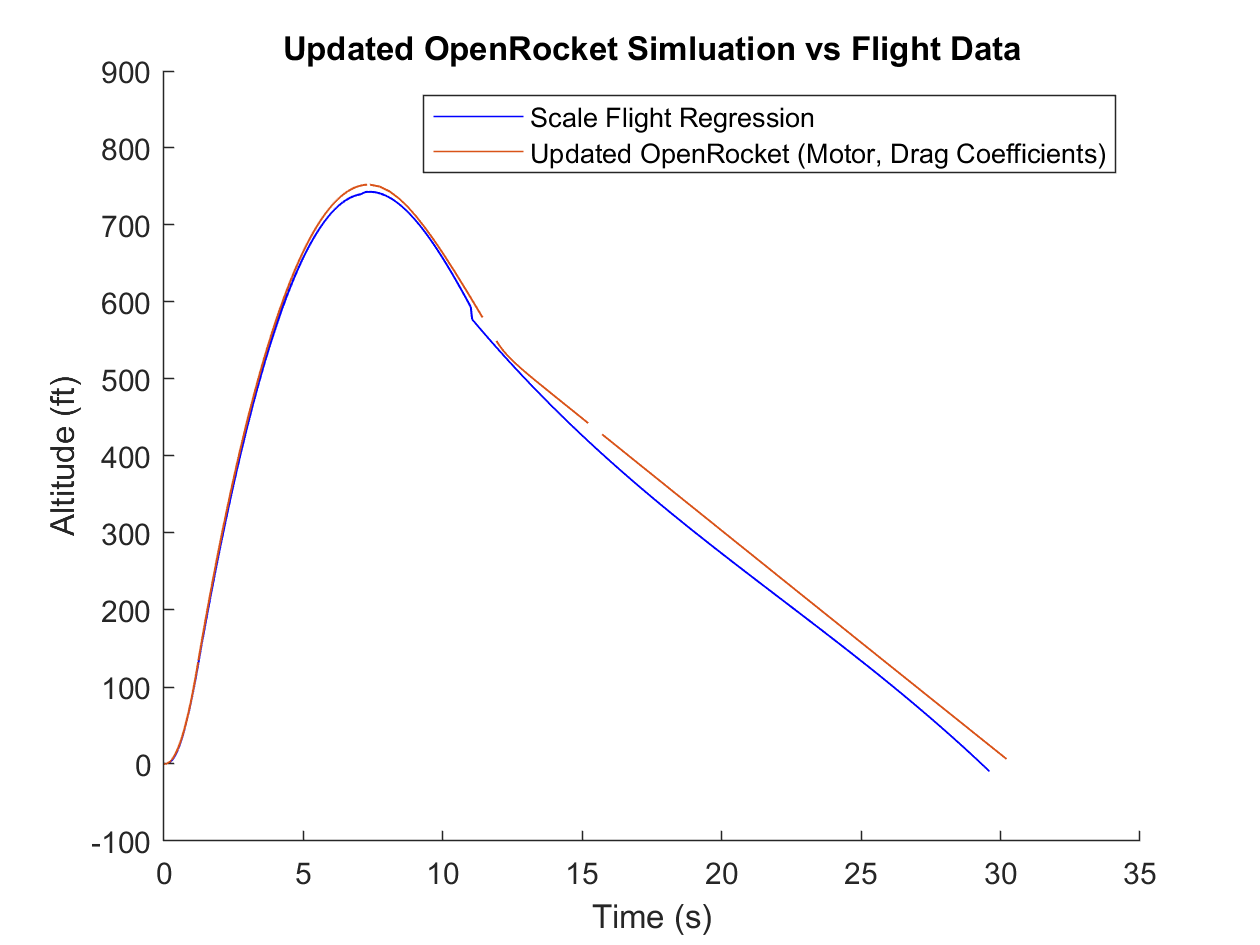

clear all
close all

data = readmatrix("Scale_Stratologger.csv");
sim = readmatrix("Scale_Original_Openrocket.csv");
regression = readmatrix("Scale_Regression.txt");
simupdate = readmatrix("Scale_Updated_Analysis.csv");
simupdatenew = readmatrix("Scale_Updated_Analysis_Different_Motor.csv");

% plot(sim(:,1),sim(:,2))
hold on
% plot(data(:,1),data(:,2))
plot(regression(:,1),regression(:,3),'color','b')
% plot(simupdate(:,1),simupdate(:,2))
plot(simupdatenew(:,1),simupdatenew(:,2))


% l = length(sim(:,1));
% x = 1:l;
% main = ones(l,1)*600;
% plot(x,main)

xlabel('Time (s)')
ylabel('Altitude (ft)') 

% title('Scale Flight Data',"FontSize",14)

title('Updated OpenRocket Simluation vs Flight Data')
legend('Scale Flight Regression',...
    'Updated OpenRocket (Motor, Drag Coefficients)')
% legend('OpenRocket Simulation','Flight Data','Flight Regression','OpenRocket Update (Parachutes)',...
%     'Openrocket Update (New Motor/Parachutes)','Main Ejection')
hold off
% xlim([0.0 50.0])
ylim([-100 900])